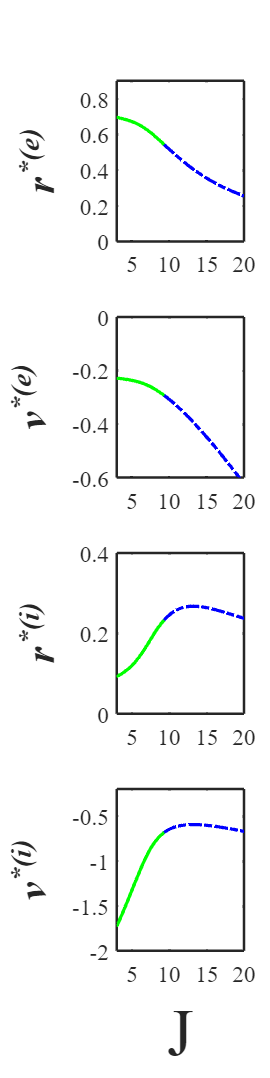

load('Hopf_Bif_CUBA_2.mat')

% Set default properties for the current script
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');


J1_CUBA2 = J_CUBA2(1:72);
J2_CUBA2 = J_CUBA2(72:end);
re1_CUBA2 = re_CUBA2(1:72);
re2_CUBA2 = re_CUBA2(72:end);
ri1_CUBA2 = ri_CUBA2(1:72);
ri2_CUBA2 = ri_CUBA2(72:end);
ve1_CUBA2 = ve_CUBA2(1:72);
ve2_CUBA2 = ve_CUBA2(72:end);
vi1_CUBA2 = vi_CUBA2(1:72);
vi2_CUBA2 = vi_CUBA2(72:end);


figure('Units', 'inches', 'Position', [0, 0, 6, 24]); % 7 pulgadas de ancho, 7 pulgadas de alto

% Primer subplot
subplot(4, 1, 1);
plot(J1_CUBA2, re1_CUBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(J2_CUBA2, re2_CUBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold off;
set(gca, 'FontSize', 14);
ylabel('r^*^{(e)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([3 20]);
ylim([0 0.9]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes

% Segundo subplot
subplot(4, 1, 2);
plot(J1_CUBA2, ve1_CUBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(J2_CUBA2, ve2_CUBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold off;
set(gca, 'FontSize', 14);
ylabel('v^*^{(e)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([3 20]);
ylim([-0.6 0]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes

% Tercer subplot
subplot(4, 1, 3);
plot(J1_CUBA2, ri1_CUBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(J2_CUBA2, ri2_CUBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold off;
set(gca, 'FontSize', 14);
ylabel('r^*^{(i)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([3 20]);
ylim([0 0.4]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes

% Cuarto subplot
subplot(4, 1, 4);
plot(J1_CUBA2, vi1_CUBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(J2_CUBA2, vi2_CUBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold off;
set(gca, 'FontSize', 14);
ylabel('v^*^{(i)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([3 20]);
ylim([-2 -0.2]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes

xlabel('J', 'FontSize', 40);

% Mejora la presentación de la figura
set(gcf, 'Color', 'w'); % Establece el color de fondo de la figura a blanco

% Alternativamente, puedes usar:
exportgraphics(gcf, 'CUBA2Hopf.png', 'Resolution', 300); % Guarda con mayor resolución